# FMCW Radar Lab: Range Response

In this lab, you will see an FMCW radar working in real time. The fundemental signal processing step for FMCW radars is taking the Fourier transform of the dechirped data. The frequency components in this data are directly proportional to the range of any reflectors in the field of view of the radar.

## System Setup

Before going through the lab, we prepare the workspace by clearing variables, closing figures, suppressing warnings.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

For this lab, we use some common system parameters to setup the radar. Each of these parameters can be tuned depending on the detection requirments of the radar, but for now we just set them to some common values.

We set the center frequency to 10 GHz. This is the frequency that the electromagnetic waves that are propagated out of the transmit antenna will be centered at. If the sweep bandwidth is 1 GHz, this means that the transmitted waveform will sweep from 9.5 GHz to 10.5 GHz.

fc = 10e9;

We set the pulse repetition frequency to 1000 Hz. This means that a new chirp will be transmitted from the radar every 1 ms.

prf = 2000;
pulse_duraton_ms = 1/prf*1e3

pulse_duraton_ms = 0.5000

We set the number of pulses to 1. This means that we will process the radar data in groups of individual pulses. Later, we acheive higher signal to noise ratio by increasing this number of integrating pulses as groups of many pulses.

nPulses = 1;

We set the sampling rate to be 1 MHz. This value must be high enough so that we can observe the frequency of the targets at our ranges of interest, and so that high frequency components of the dechirped signal do not get aliased to look like lower frequency components.

fs = 1e6;

We also set the ramp bandwidth of the system. This is a critical parameter for radars, because it impacts range resolution. The higher this value is, the more able we are to distinguish between two closely spaced targets. Try changing this parameter to see how the range response is impacted.

rampbandwidth = 500e6;

Finally, we set up the FMCW radar with these key system parameters. Each of the outputs of the function below are responsible for controlling some part of the radar.

[rx,tx,bf,bf_TDD] = setupLabRadar(fc,prf,nPulses,fs,rampbandwidth);

## Data Collection

With our FMCW radar configured. It is time to capture some radar data and visualize the range response.

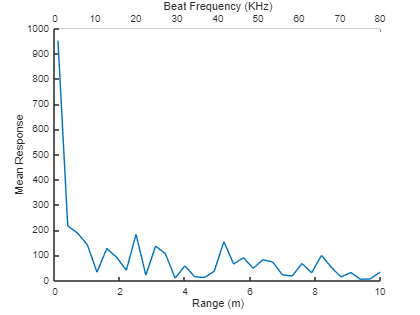

% Run time in seconds
tCapture = 30;

% Get the min and max ranges to include on the plot
minRange = 0;
maxRange = 10;
calRange = 0.5;

% Create a range response
tSweep = double(bf.FrequencyDeviationTime)/1e6;
sweepSlope = rampbandwidth/tSweep;
rr = phased.RangeResponse(RangeMethod="FFT",SweepSlope=sweepSlope,SampleRate=fs);

% Create axes to plot range response and beat frequency on the same figure
f = figure;
freqAx = axes(f);
hold(freqAx,"on");
rangeAx = axes(f);
hold(rangeAx,"on");

% Format range axes
xlabel(rangeAx,'Range (m)');
ylabel(rangeAx,'Mean Response');
rangeline = plot(rangeAx,0,0);

% Format freq axes to show beat frequencies
xlabel(freqAx,'Beat Frequency (KHz)');
freqAx.XAxisLocation = "top";
freqAx.YAxis.Visible = false;
freqline = plot(freqAx,0,0);

% Set positions of axes to be the same
rangeAx.Position = freqAx.Position;

% Capture the first waveform which typically has 0 values
captureTransmitWaveform(rx,tx,bf);

t = tic;
while toc(t) < tCapture
    % capture data
    data = captureTransmitWaveform(rx,tx,bf);

    % Arrange data into pulses for processing
    data = arrangePulseData(data,rx,bf,bf_TDD);

    % Get the range-Response for just one pulse
    [resp,range] = rr(data(:,1));

    % Generate the beat frequencies corresponding to ranges
    bfreq = linspace(-rr.SampleRate/2,rr.SampleRate/2,length(range));

    % Adjust the range for calibration range
    range = range - calRange;

    % Get range of interest
    keepRange = range >= minRange & range <= maxRange;

    % Plot the response on the range and freq axes
    set(rangeline,'XData',range(keepRange),'YData',abs(resp(keepRange)));
    set(freqline,'XData',bfreq(keepRange)/1e3,'YData',abs(resp(keepRange)));
    drawnow;
end


% Disable Pluto
cleanupAntenna(rx,tx,bf,bf_TDD);